# EMT Basic Functionalities

## **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'L-Town.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "L-Town.inp"...
Input File "L-Town.inp" loaded successfully.


G =   epanet with properties:

                                   ph: [1×1 lib.pointer]
                   ControlLevelValues: [3.90000009536743 2.40000009536743]
                     ControlLinkIndex: [906 906]
                     ControlNodeIndex: [785 785]
                         ControlRules: []
                    ControlRulesCount: 2
                             Controls: [1×2 struct]
                      ControlSettings: [0 1]
                         ControlTypes: {'HIGHLEVEL'  'LOWLEVEL'}
                    ControlTypesIndex: [1 0]
                           CurveCount: 1
                           CurveIndex: 1
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1
                      DemandModelPexp: 0.5
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits

## Data and Methods in Toolkit

What data variables are in the class?

properties(G)


Properties for class epanet:

    ph
    ControlLevelValues
    ControlLinkIndex
    ControlNodeIndex
    ControlRules
    ControlRulesCount
    Controls
    ControlSettings
    ControlTypes
    ControlTypesIndex
    CurveCount
    CurveIndex
    CurvesInfo
    DemandModelCode
    DemandModelPmin
    DemandModelPreq
    DemandModelPexp
    DemandModelType
    EnergyEfficiencyUnits
    EnergyUnits
    Errcode
    InputFile
    Iterations
    LibEPANET
    LibEPANETpath
    libFunctions
    LinkBulkReactionCoeff
    LinkCount
    LinkDiameter
    LinkFlowUnits
    LinkFrictionFactorUnits
    LinkIndex
    LinkInitialSetting
    LinkInitialStatus
    LinkLength
    LinkLengthsUnits
    LinkMinorLossCoeff
    LinkMinorLossCoeffUnits
    LinkNameID
    LinkPipeCount
    LinkPipeDiameterUnits
    LinkPipeIndex
    LinkPipeNameID
    LinkPipeRoughnessCoeffUnits
    LinkPumpCount
    LinkPumpHeadCurveIndex
    LinkPumpIndex
    LinkPumpNameID
    LinkPumpPatternIndex
    LinkPumpPatternNameID

What methods/functions are in the toolkit? 

methods(G) 


Methods for class epanet:

BinClose                                     
BinUpdateClass                               
Binplot                                      
addBinCVPipe                                 
addBinControl                                
addBinCurveEfficiency                        
addBinCurveHeadloss                          
addBinCurvePump                              
addBinCurveVolume                            
addBinLinkPipe                               
addBinLinkPump                               
addBinLinkValve                              
addBinLinkVertices                           
addBinNodeJunction                           
addBinNodeReservoir                          
addBinNodeTank                               
addBinPattern                                
addBinPipe                                   
addBinPump                                   
addBinValveFCV                               
addBinValveGPV                               
addBin

 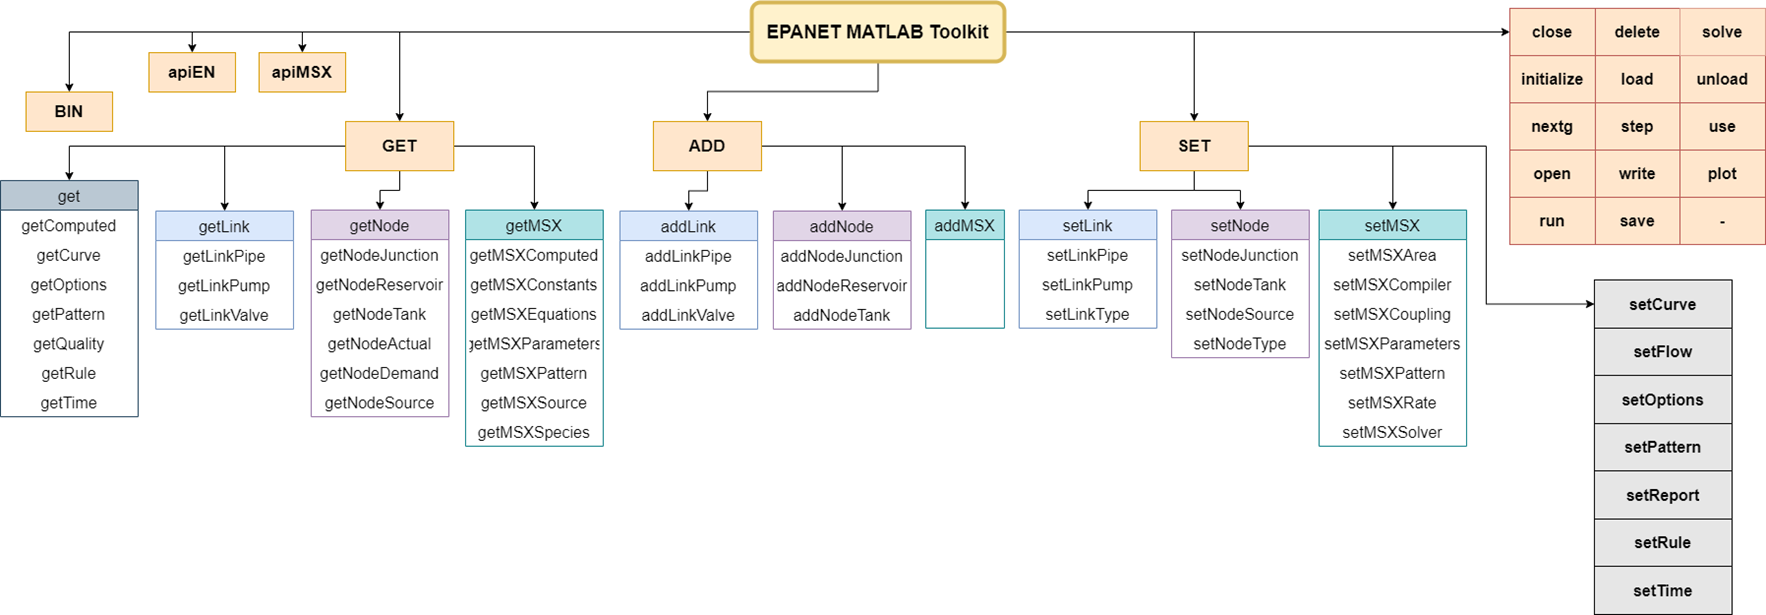

## **Need help?**

**Just type "help" followed by the command**

help G.getLinkDiameter

--- help for epanet/getLinkDiameter ---

  Retrieves the value of link diameters.
  Pipe/valve diameter
 
  Example 1:
     d.getLinkDiameter      % Retrieves the value of all link diameters
 
  Example 2:
     d.getLinkDiameter(1)   % Retrieves the value of the first link diameter
 
  See also getLinkType, getLinksInfo, getLinkLength,
           getLinkRoughnessCoeff, getLinkMinorLossCoeff.



help G.setNodeBaseDemands

--- help for epanet/setNodeBaseDemands ---

  Sets the values of demand for nodes.
 
  The examples are based on d=epanet('BWSN_Network_1.inp');
 
  Example 1:
    index_node = 1;
    d.getNodeBaseDemands{1}(index_node)                       % Retrieves the demand of the 1st node
    demand = 5;
    d.setNodeBaseDemands(index_node, demand);                 % Sets the demand of the 1st node
    d.getNodeBaseDemands{1}(index_node)
 
  Example 2:
    nodeIndex = 1:5;
    d.getNodeBaseDemands{1}(nodeIndex)                        % Retrieves the demands of first 5 nodes
    demands = [10, 5, 15, 20, 5];
    d.setNodeBaseDemands(nodeIndex, demands)                  % Sets the demands of first 5 nodes
    d.getNodeBaseDemands{1}(nodeIndex)
 
  Example 3:
    demands = d.getNodeBaseDemands{1};                        % Retrieves the demands of all nodes
    demands_new = demands + 15;
    d.setNodeBaseDemands(demands_new);     

**Exercise: Ask help for any EMT method**

% write "G." and press "Tab" key to find a command




## **Plot network topology**

## 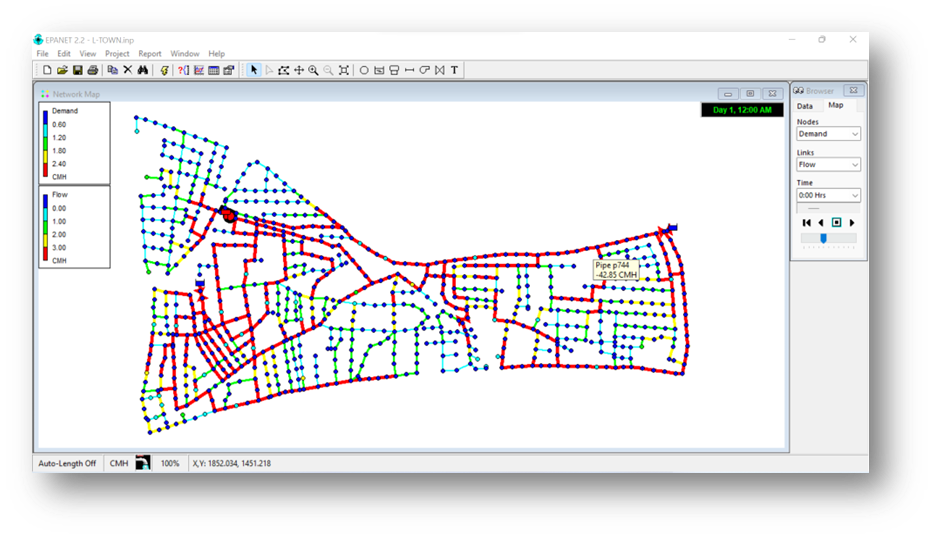

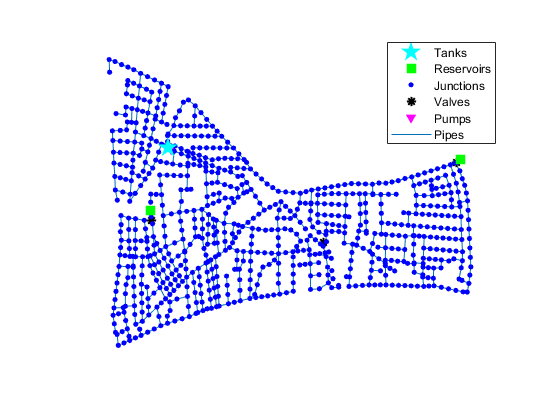

% For a simple plot, use G.plot. 
G.plot;

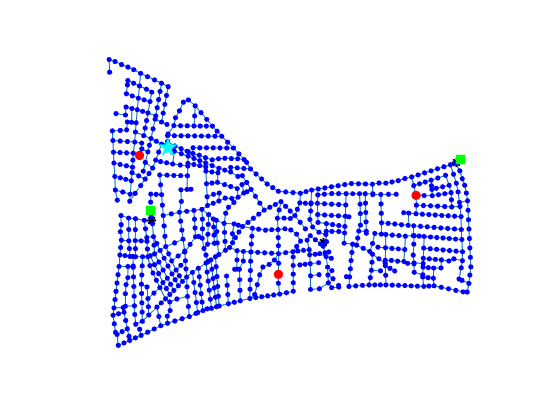

% Highlight specific nodes
G.plot('highlightnode',{'n616', 'n281', 'n31'});

## **Getting information from links (pipes,pumps,valves)**

## 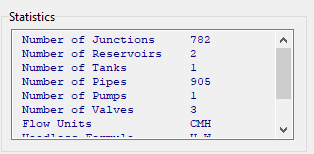

linkCount = G.getLinkCount

linkCount = int32
   909


pipeCount = G.getLinkPipeCount

pipeCount =    905


pumpCount = G.getLinkPumpCount

pumpCount =      1


valveCount = G.getLinkValveCount

valveCount = int32
   3


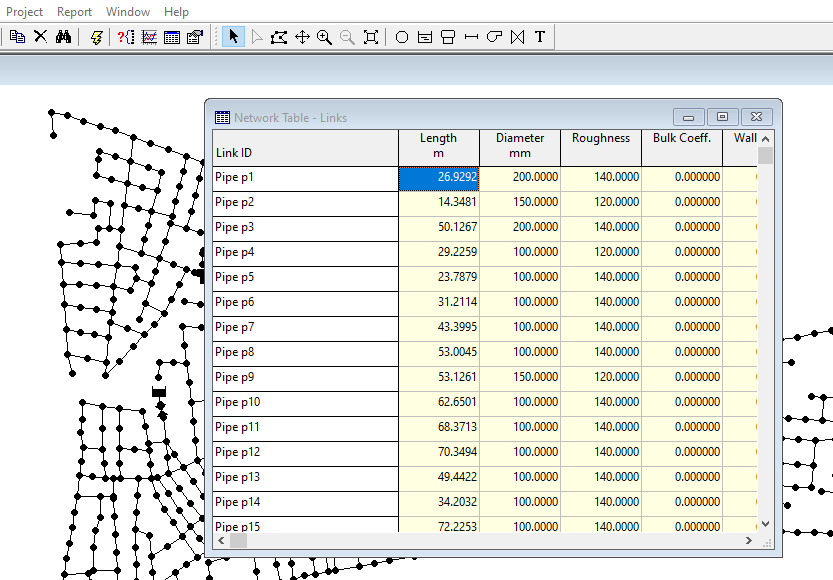

diameters = G.getLinkDiameter

diameters =    200   150   200   100   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


pipelength = G.getLinkLength(1:3)

pipelength =             26.92919921875          14.3480997085571          50.1267013549805


LinkNameID = G.getLinkNameID

LinkNameID = 1×909 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p8

PipeNameID = G.getLinkPipeNameID

PipeNameID = 1×905 cell array
  Columns 1 through 842

    {'p1'}    {'p2'}    {'p3'}    {'p4'}    {'p5'}    {'p6'}    {'p7'}    {'p8'}    {'p9'}    {'p10'}    {'p11'}    {'p12'}    {'p13'}    {'p14'}    {'p15'}    {'p16'}    {'p17'}    {'p18'}    {'p19'}    {'p20'}    {'p21'}    {'p22'}    {'p23'}    {'p24'}    {'p25'}    {'p26'}    {'p27'}    {'p28'}    {'p29'}    {'p30'}    {'p31'}    {'p32'}    {'p33'}    {'p34'}    {'p35'}    {'p36'}    {'p37'}    {'p38'}    {'p39'}    {'p40'}    {'p41'}    {'p42'}    {'p43'}    {'p44'}    {'p45'}    {'p46'}    {'p47'}    {'p48'}    {'p49'}    {'p50'}    {'p51'}    {'p52'}    {'p53'}    {'p54'}    {'p55'}    {'p56'}    {'p57'}    {'p58'}    {'p59'}    {'p60'}    {'p61'}    {'p62'}    {'p63'}    {'p64'}    {'p65'}    {'p66'}    {'p67'}    {'p68'}    {'p69'}    {'p70'}    {'p71'}    {'p72'}    {'p73'}    {'p74'}    {'p75'}    {'p76'}    {'p77'}    {'p78'}    {'p79'}    {'p80'}    {'p81'}    {'p82'}    {'p83'}    {'p84'}    {'p85'}    {'p86'}    {'p8

PumpNameID = G.getLinkPumpNameID

PumpNameID = 1×1 cell array
    {'PUMP_1'}


ValveNameID = G.getLinkValveNameID

ValveNameID = 1×3 cell array
    {'PRV-1'}    {'PRV-2'}    {'PRV-3'}


## **Getting information from nodes (junctions,tanks,reservoirs)**

## 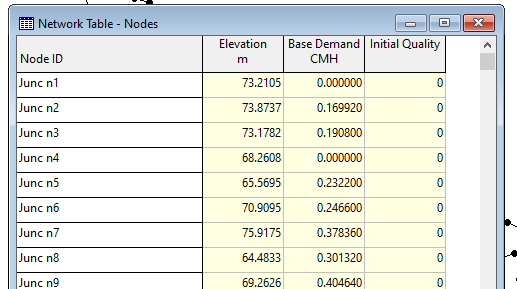

nodeCount = G.getNodeCount

nodeCount = int32
   785


junctionCount = G.getNodeJunctionCount

junctionCount = int32
   782


tankCount = G.getNodeTankCount

tankCount =      1


reservoirCount = G.getNodeReservoirCount

reservoirCount =      2


elevations = G.getNodeElevations([1, 2, 3])

elevations =           73.2105026245117          73.8737030029297          73.1781997680664



nodeID = G.getNodeNameID

nodeID = 1×785 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}    

junctionID = G.getNodeJunctionNameID

junctionID = 1×782 cell array
    {'n1'}    {'n2'}    {'n3'}    {'n4'}    {'n5'}    {'n6'}    {'n7'}    {'n8'}    {'n9'}    {'n10'}    {'n11'}    {'n12'}    {'n13'}    {'n14'}    {'n15'}    {'n16'}    {'n17'}    {'n18'}    {'n19'}    {'n20'}    {'n21'}    {'n22'}    {'n23'}    {'n24'}    {'n25'}    {'n26'}    {'n27'}    {'n28'}    {'n29'}    {'n30'}    {'n31'}    {'n32'}    {'n33'}    {'n34'}    {'n35'}    {'n36'}    {'n37'}    {'n38'}    {'n39'}    {'n40'}    {'n41'}    {'n42'}    {'n43'}    {'n44'}    {'n45'}    {'n46'}    {'n47'}    {'n48'}    {'n49'}    {'n50'}    {'n51'}    {'n52'}    {'n53'}    {'n54'}    {'n55'}    {'n56'}    {'n57'}    {'n58'}    {'n59'}    {'n60'}    {'n61'}    {'n62'}    {'n63'}    {'n64'}    {'n65'}    {'n66'}    {'n67'}    {'n68'}    {'n69'}    {'n70'}    {'n71'}    {'n72'}    {'n73'}    {'n74'}    {'n75'}    {'n76'}    {'n77'}    {'n78'}    {'n79'}    {'n80'}    {'n81'}    {'n82'}    {'n83'}    {'n84'}    {'n85'}    {'n86'}    {'n87'}    {'n88'}    {'n89'}

tankID = G.getNodeTankNameID

tankID = 1×1 cell array
    {'T1'}


reservoirID = G.getNodeReservoirNameID

reservoirID = 1×2 cell array
    {'R1'}    {'R2'}



%% Try it yourself below


## **Demands**

 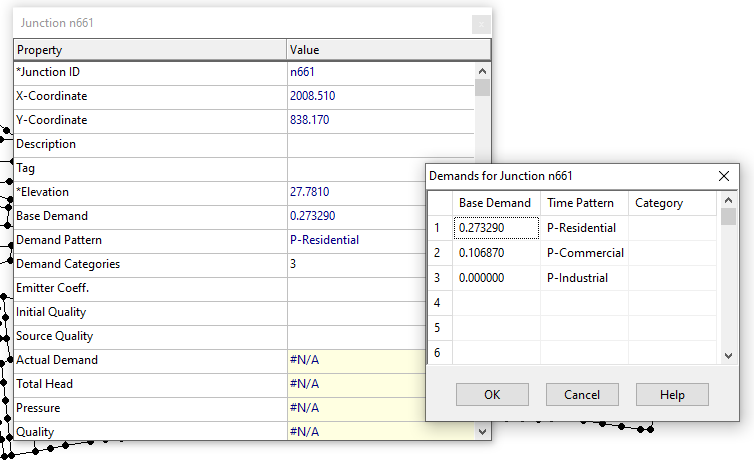

demandcategories = G.getNodeDemandCategoriesNumber

demandcategories =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


demands = G.getNodeBaseDemands

demands = 1×3 cell array
    {1×785 double}    {1×785 double}    {1×785 double}


demandscategory1 = G.getNodeBaseDemands{1} % Get categories 1

demandscategory1 =                          0          0.16991999745369         0.190799996256828                         0         0.232199996709824           0.2466000020504         0.378360003232956         0.301319986581802          0.40463998913765        0.0842399969696999         0.544319987297058        0.0583200007677078         0.235799998044968        0.0194400008767843         0.191520005464554        0.0964799970388412         0.448920011520386        0.0723600015044212          0.12924000620842          0.14436000585556        0.0608399994671345         0.150839999318123        0.0286899991333485         0.043919999152422                         0       0.00467999977990985         0.130679994821548                         0        0.0489600002765656         0.305640012025833         0.116279996931553        0.0799200013279915        0.0028800000436604         0.112319998443127                         0         0.266400009393692        0.0846000015735626         0.18888999


NodeIndex = G.getNodeIndex('n661')   % Retrieves the node index given the ID label of the node

NodeIndex = int32
   661


G.getNodeBaseDemands(NodeIndex)   % Get node base demand with categories for specific node index

ans = 1×3 cell array
    {[0.273290008306503]}    {[0.106870003044605]}    {[0]}


## **Change parameters in network**

**Change diameter**

%change pipe diameter
d4 = G.getLinkDiameter(4)

d4 =    100


diameters = G.getLinkDiameter

diameters =    200   150   200   100   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


diameters(4) = 200

diameters =    200   150   200   200   100   100   100   100   150   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   150   100   100   200   150   100   100   100   100   100   100   100   100   200   100


G.setLinkDiameter(diameters)
d4new = G.getLinkDiameter(4)

d4new =    200


**Change elevation**

%change node elevation
e4 = G.getNodeElevations(4)

e4 =           68.2608032226562


elevations = G.getNodeElevations

elevations =           73.2105026245117          73.8737030029297          73.1781997680664          68.2608032226562          65.5695037841797          70.9095001220703          75.9175033569336          64.4832992553711          69.2626037597656          74.3469009399414          63.0587997436523          68.2274017333984          61.9901008605957          68.5804977416992          70.9492034912109          68.7985992431641          60.5934982299805          67.1419982910156          73.3626022338867          65.9549026489258          59.6848983764648           76.117301940918          64.2052001953125          67.8217010498047          58.9716987609863           61.630500793457          65.7762985229492          61.4047012329102          71.5429000854492          75.3299026489258          65.0058975219726          71.1589965820312          60.5901985168457          65.8481979370117          59.6258010864258          70.1958999633789          63.9171981811523          58.579399108886

elevations(4) = 70

elevations =           73.2105026245117          73.8737030029297          73.1781997680664                        70          65.5695037841797          70.9095001220703          75.9175033569336          64.4832992553711          69.2626037597656          74.3469009399414          63.0587997436523          68.2274017333984          61.9901008605957          68.5804977416992          70.9492034912109          68.7985992431641          60.5934982299805          67.1419982910156          73.3626022338867          65.9549026489258          59.6848983764648           76.117301940918          64.2052001953125          67.8217010498047          58.9716987609863           61.630500793457          65.7762985229492          61.4047012329102          71.5429000854492          75.3299026489258          65.0058975219726          71.1589965820312          60.5901985168457          65.8481979370117          59.6258010864258          70.1958999633789          63.9171981811523          58.579399108886

G.setNodeElevations(elevations)
e4new = G.getNodeElevations(4)

e4new =     70


## **Patterns**

G.getPatternCount

ans = int32
   3


PatternsNames = G.getPatternNameID

PatternsNames = 1×3 cell array
    {'P-Residential'}    {'P-Commercial'}    {'P-Industrial'}


Patterns = G.getPattern

Patterns =          0.772899985313416         0.748000025749207          0.72299998998642         0.698599994182587         0.675100028514862         0.652499973773956         0.630500018596649         0.608900010585785         0.587400019168854         0.565900027751923         0.544600009918213         0.523599982261658         0.503099977970123         0.483300000429153         0.464300006628036         0.445899993181229         0.427899986505508         0.410299986600876         0.392899990081787         0.375699996948242         0.358999997377396         0.342999994754791         0.327899992465973         0.313899993896484          0.30129998922348         0.289900004863739         0.279500007629395         0.270000010728836         0.261000007390976          0.25229999423027         0.243900001049042         0.235499992966652         0.227300003170967         0.219200000166893         0.211400002241135         0.204199999570847          0.19760000705719         0.191799998283386 

**Plot residential pattern**

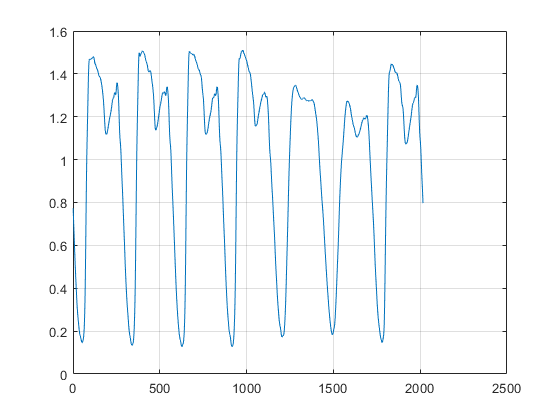

figure
plot(Patterns(1,:)); grid on

## 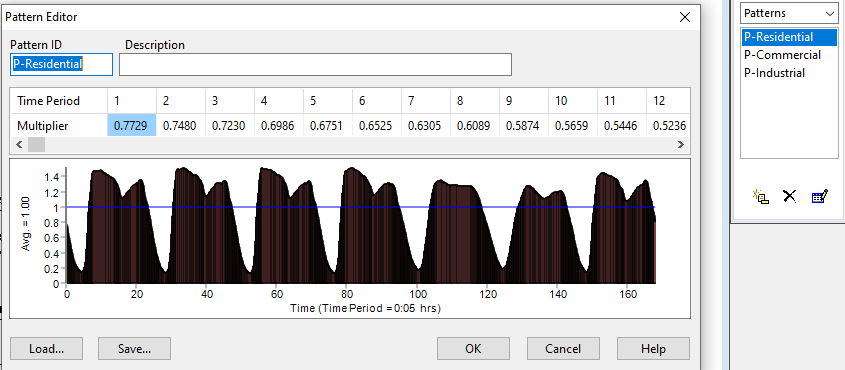

%adding a pattern (name is string of 5 random letters a-z)
patternID = char(randi([97 122],1,5)) 

patternID = 'zkgvw'

patternMult = Patterns(2,:)*0.5

patternMult =          0.458700001239777         0.452650010585785         0.446449995040894         0.440100014209747         0.433649986982346         0.427049994468689         0.420300006866455         0.413450002670288         0.406399995088577         0.399399995803833         0.392399996519089         0.385699987411499          0.37924998998642         0.373250007629395         0.367549985647202         0.362100005149841         0.356799989938736         0.351449996232986          0.34595000743866           0.3403500020504         0.334650009870529         0.328999996185303         0.323650002479553         0.318699985742569         0.314350008964539         0.310550004243851         0.307300001382828         0.304399996995926         0.301699995994568          0.29899999499321         0.296149998903275         0.293099999427795         0.289849996566772         0.286500006914139         0.283149987459183         0.280000001192093         0.277150005102158         0.2745999991893

patternIndex = G.addPattern(patternID, patternMult)

patternIndex = int32
   4


Patterns = G.getPattern

Patterns =          0.772899985313416         0.748000025749207          0.72299998998642         0.698599994182587         0.675100028514862         0.652499973773956         0.630500018596649         0.608900010585785         0.587400019168854         0.565900027751923         0.544600009918213         0.523599982261658         0.503099977970123         0.483300000429153         0.464300006628036         0.445899993181229         0.427899986505508         0.410299986600876         0.392899990081787         0.375699996948242         0.358999997377396         0.342999994754791         0.327899992465973         0.313899993896484          0.30129998922348         0.289900004863739         0.279500007629395         0.270000010728836         0.261000007390976          0.25229999423027         0.243900001049042         0.235499992966652         0.227300003170967         0.219200000166893         0.211400002241135         0.204199999570847          0.19760000705719         0.191799998283386 

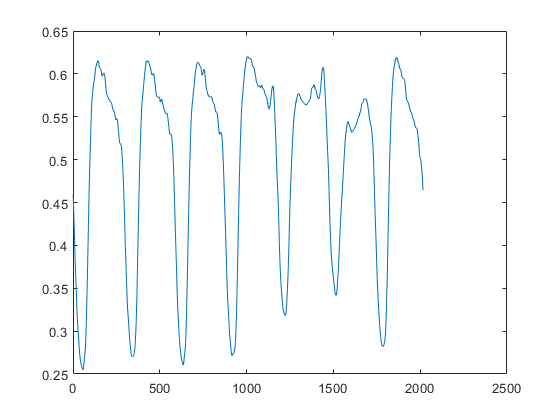

%plot new pattern
figure
plot(Patterns(patternIndex,:))

## **Simulation options**

**Time options**

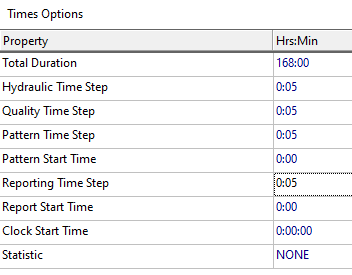

SimulationDuration = G.getTimeSimulationDuration %in seconds

SimulationDuration = int32
   604800


SimulationDurationHours = SimulationDuration/3600

SimulationDurationHours = int32
   168



HydraulicStep = G.getTimeHydraulicStep %in seconds

HydraulicStep = int32
   300


QualityStep = G.getTimeQualityStep %in seconds

QualityStep = int32
   300


PatternStep = G.getTimePatternStep %in seconds

PatternStep = int32
   300



ReportingStep = G.getTimeReportingStep %in seconds

ReportingStep = int32
   300


ReportingStart = G.getTimeReportingStart

ReportingStart = int32
   0


PatternStart = G.getTimePatternStart

PatternStart = int32
   0


**Hydraulic options**

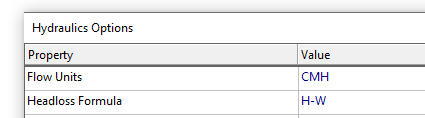

Units = G.getUnits

Units = struct with fields:
                    Units_SI_Metric: 1
                 Units_US_Customary: 0
                      LinkFlowUnits: 'CMH'
                  NodePressureUnits: 'meters'
                PatternDemandsUnits: 'CMH'
              LinkPipeDiameterUnits: 'millimeters'
              NodeTankDiameterUnits: 'meters'
              EnergyEfficiencyUnits: 'percent'
                 NodeElevationUnits: 'meters'
                    NodeDemandUnits: 'CMH'
        NodeEmitterCoefficientUnits: 'flow units @ 1 meter drop'
                        EnergyUnits: 'kwatt-hours'
            LinkFrictionFactorUnits: 'unitless'
                      NodeHeadUnits: 'meters'
                   LinkLengthsUnits: 'meters'
            LinkMinorLossCoeffUnits: 'unitless'
                 LinkPumpPowerUnits: 'kwatts'
      QualityReactionCoeffBulkUnits: '1/day (1st-order)'
      QualityReactionCoeffWallUnits: 'mass/sq-m/day(0-order), meters/day (1st-order)'
        LinkPipeRoughnessCoeffUnits:

FlowUnits = G.getFlowUnits

FlowUnits = 'CMH'

PressureUnits = G.NodePressureUnits

PressureUnits = 'meters'

HeadLossFormula = G.getOptionsHeadLossFormula

HeadLossFormula = 'HW'

**Setup quality options**

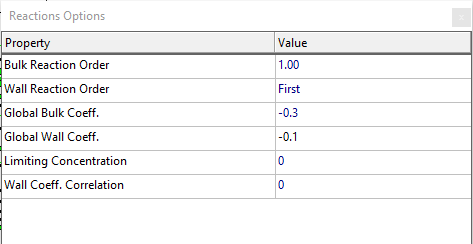

G.setQualityType('chlorine','mg/L') %set quality type

zeroNodes = zeros(1,G.NodeCount)

zeroNodes =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


G.setNodeInitialQuality(zeroNodes) %setting initial chlorine level at 0  mg/L

brk = -0.3 * ones(1,G.LinkCount)

brk =                       -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3                      -0.3      

G.setLinkBulkReactionCoeff(brk) %setting Bulk Reaction Coefficient

wrk = -0.1 * ones(1,G.LinkCount)

wrk =                       -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1                      -0.1      

G.setLinkWallReactionCoeff(wrk) %setting Pipe wall Reaction Coefficient

BulkReactionOrder = G.getOptionsPipeBulkReactionOrder

BulkReactionOrder = single
     1


PipeWallReactionOrder = G.getOptionsPipeWallReactionOrder

PipeWallReactionOrder = single
     1


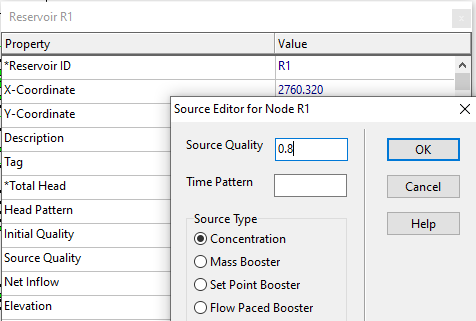

ReservoirsIndex = G.getNodeReservoirIndex

ReservoirsIndex =    783   784


help G.setNodeSourceType

--- help for epanet/setNodeSourceType ---

  Sets the values of quality source type.
 
  Types of external water quality sources that can be set:
    1) CONCEN      Sets the concentration of external inflow entering a node
    2) MASS        Injects a given mass/minute into a node
    3) SETPOINT    Sets the concentration leaving a node to a given value
    4) FLOWPACED   Adds a given value to the concentration leaving a node
 
  Example:
    nodeIndex = 1;
    d.getNodeSourceType{nodeIndex}               % Retrieves the quality source type of the 1st node
    sourceType = 'MASS';
    d.setNodeSourceType(nodeIndex, sourceType)   % Sets the quality source type = 'MASS' to the 1st node
    d.getNodeSourceType{nodeIndex}
 
  See also getNodeSourceType, setNodeSourceQuality, setNodeSourcePatternInde


for i=1:length(ReservoirsIndex) %number of reservoirs
    G.setNodeSourceType(ReservoirsIndex(i), 'CONCEN')
    G.setNodeSourceQuality(ReservoirsIndex(i),0.8)
end

NodeSourceQuality = G.getNodeSourceQuality(ReservoirsIndex)

NodeSourceQuality =          0.800000011920929         0.800000011920929
